# 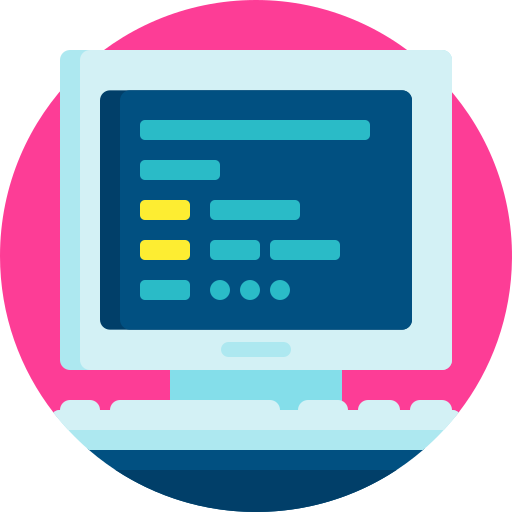

# Virtual Lab 4: System characterisation

**Chapter 5-6**

- This live script is intended to be used with the code shown. Select the `VIEW` tab and switch to `Output on Right`.

- This script has been sectioned off — you can use `Run Section `(CMD/CNTL+ENTER) instead of` Run `when in a particular section. This will only evaluate code in the section. 

- This virtual lab requires the following `MATLAB` toolboxes: Control Systems Toolbox, Symbolic Math Toolbox.

- You can use the `help` function to get information on a function within the `MATLAB Command Window`, e.g. `help laplace`.

## First-order systems

The generalised first-order system without zeros can be described by the transfer function below. 

$P(s)=\frac{K}{s-p}$,

where $p\in \mathbb{R}$ is the sole pole of $P(s)$. If the input is a unit step, $U(s)=1/s$, the Laplace transform of the step response is given by

$Y(s)=P(s)U(s)=\frac{K}{s(s-p)}$.

The partial fraction expansion of $Y(s)$ follows as


$$Y(s)=\frac{A}{s}+\frac{B}{s-p}=-\frac{K/p}{s}+\frac{K/p}{s-p}$$


Taking the inverse transform, the step response is given by

$y(t)=y_f(t)+y_n(t)=-\frac{K}{p}+\frac{K}{p}e^{pt}=\frac{K}{p}\left(e^{pt}-1\right)$,

where the structure of:

- $y_f(t)=-\frac{K}{p}$ is a result of the pole in $U(s)$ at the origin, and 

- $y_n(t)=\frac{K}{p}e^{-at}$ is from the pole in $G(s)$ at $s=p$.

$y_f(t)$ is referred to as the forced response, and $y_n(t)$ is the natural response. The unit step response, $y(t)$, can be generated using the code below.

clear
s=tf('s');
K = 3.5;
p = -6.5;    
P = K/(s-p);
figure,clf
[y,t] = step(P);
plot(t,y,lineWidth=2)
xlabel('$t$ (seconds)',Interpreter='latex',FontSize=15)
ylabel('$y(t)$',Interpreter='latex',FontSize=15)
title('$y(t)=\frac{K}{p}\left(e^{pt}-1\right)$',Interpreter='latex',FontSize=14,Color='#0072BD')

### Steady-state value

If we have an equation that defines the output response $y(t)$, then we can easily determine the steady-state output reponse by evaluating the limit as time tends to infinity:

$y(\infty)=\lim_{t\rightarrow\infty}y(t)=\lim_{t\rightarrow\infty}\frac{K}{p}\left(e^{pt}-1\right)=-\frac{K}{p}=A_{s}$.

If the output response is bounded, requiring $p<0$ and a bounded input signal, then we can similarly determine $y(\infty)$ using FVT in the Laplace domain, namely

$y(\infty)=\lim_{s\rightarrow 0}sY(s)$.

####  Question 1: Determine the steady-state value of $Y(s)=\frac{10}{s(s+1)}$ using final-value theorem. 

*Hint: you can use MATLAB to confirm your result.*

%code block (if required)


### Time constant and exponential frequency

Assuming the response is bounded, we define $T_c=-\frac{1}{p}$ as the **time constant** of the response. This corresponds with the time it takes for the first-order step response to rise to 63% of its final value, which is determined using

$y(T_c)=y(-1/p)=\frac{K}{p}\left(e^{-1}-1\right)\approx -0.63\frac{K}{p} = 0.63A_{s}$.

We can reparameterise $P(s)$ using $T_c$ and $A_s$ as

$P(s)=\frac{K}{s-p}=\frac{-K/p}{-s/p+1}=\frac{A_{s}}{T_cs+1}$.

*Confirm the above results by hand before visualising the settling time with the code below.*

s=tf('s');
K = 5;
p = -3.5;
P = K/(s-p);
figure,clf,hold on
[y,t] = step(P);
plot(t,y,lineWidth=2)
line(-1/p*[1 1],[0 -0.63*K/p],Color='red')
line([0 -1/p],-0.63*K/p*[1 1],Color='red')
plot(-1/p,-0.63*K/p,'ro',MarkerFaceColor='r')
text(-1/p,-0.05*K/p,['$T_c=$',num2str(-1/p,2)],Interpreter='latex')

xlabel('$t$ (seconds)',Interpreter='latex',FontSize=15)
ylabel('$y(t)$',Interpreter='latex',FontSize=15)
title('$y(t)=\frac{K}{p}\left(e^{pt}-1\right)$',Interpreter='latex',FontSize=14,Color='#0072BD')

The reciprocal of the time constant has the units (1/seconds), or frequency. Thus, we call the parameter $\alpha=-p=1/T_c$ the **exponential frequency**. Note that we can also represent $P(s)$ using our exponential frequency as

$P(s)=\frac{K}{s-p}=\frac{K}{s+a}=\frac{A_{s}}{s/\alpha+1}$.

It is important to see that all the above representations of $P(s)$ are *equivalent*, but they use different *parameterisations*.

We can determine the initial rate of change of $y(t)$ by determining the time-derivative, $\dot{y}(t)$, and then evaluating it at $t=0$:

$\lim_{t\rightarrow 0}\dot{y}(t) = \lim_{t\rightarrow 0}Ke^{pt} =K$.

Thus, the gain term, $K$, will determine how quickly the system initially responds. 

####  Question 2: Given $Y(s)=\frac{10}{s(s+1)}$, and $U(s)=\frac{1}{s}$, determine the time constant of $P(s)$ .

*Hint: you can use MATLAB to confirm your result.*

%code block (if required)


### Settling time

**Settling time **is defined as the time for the response to *reach, and stay within*, $2\%$ of its final value of $y(\infty)$. Given that we know the response has no overshoot or oscillatory behaviour, we know that once the response enters the $2\%$ band, it will stay in the band. Letting $y(t)=0.98A_s$, and solving for time, $t$, we find the settling time to be

$T_s=\frac{4}{-p}=\frac{4}{\alpha}=4T_c$.

*Confirm this by hand before visualising the settling time with the code below.*

s=tf('s');
K = 3.5;
p = -7.5;
P = K/(s-p);
figure,clf,hold on
[y,t] = step(P);
plot(t,y,lineWidth=2)
yline(-1.02*K/p,'k--')
yline(-0.98*K/p,'k--')
line(-4/p*[1 1],[0 -0.98*K/p],Color='red')
plot(-4/p,-0.98*K/p,'ro',MarkerFaceColor='r')
text(-4/p,-0.05*K/p,['$T_s=$',num2str(-4/p,2)],Interpreter='latex')
xlabel('$t$ (seconds)',Interpreter='latex',FontSize=15)
ylabel('$y(t)$',Interpreter='latex',FontSize=15)
title('$y(t)=\frac{K}{p}\left(e^{pt}-1\right)$',Interpreter='latex',FontSize=14,Color='#0072BD')

####  Question 3: Determine the $2\%$ settling time of $Y(s)=\frac{10}{s(s+1)}$ by hand.

*Hint: you can use MATLAB to confirm your result.*

%code block (if required)


### First-order transfer functions via testing

Often it is not possible or practical to obtain a system's transfer function analytically. Perhaps the system is closed, and the component parts are not easily identifiable. Since the transfer function is a representation of the system from input to output, the system's step response can lead to a representation even though the inner construction may not be known. With a step input, we can measure the time constant and the steady-state value of the step response, from which the transfer function can be calculated.

Consider the canonical first-order structure of 

$P(s)=\frac{A_s}{T_cs+1}$.

Given a unit step input, the corresponding output response in the Laplace domain is

$Y(s)=P(s)U(s)=\frac{A_s}{s(T_cs+1)}$.

####   **Task: **The code below generates the unit step response for an unknown first-order system. Using MATLAB and your understanding of the plant parameterisation above, determine the unknown transfer function model.

*Hint 1: After clicking on a figure, you can place a datatip on the data, to get (x,y) information at a particular point.*

*Hint 2: once you find your estimated *$P(s)$, simulate it on the same figure to confirm that the two step responses match.

%task
P = ss(-0.33,1,1.67,0);
[y,t] = step(P);
%add code below this point

figure,clf,hold on,grid on
plot(t,y,LineWidth=2,color='black')


####  Question 4: What is the value of $A_s$? Provide your answer to two decimal places.

####  Question 5: What is the value of $T_c$? Provide your answer to two decimal places.

####  Question 6: What is the $2\%$ settling time of the unit step response? Provide your answer to two decimal places.

####  Question 7: Match the first-order unit step responses below to the options provided in Amathuba.

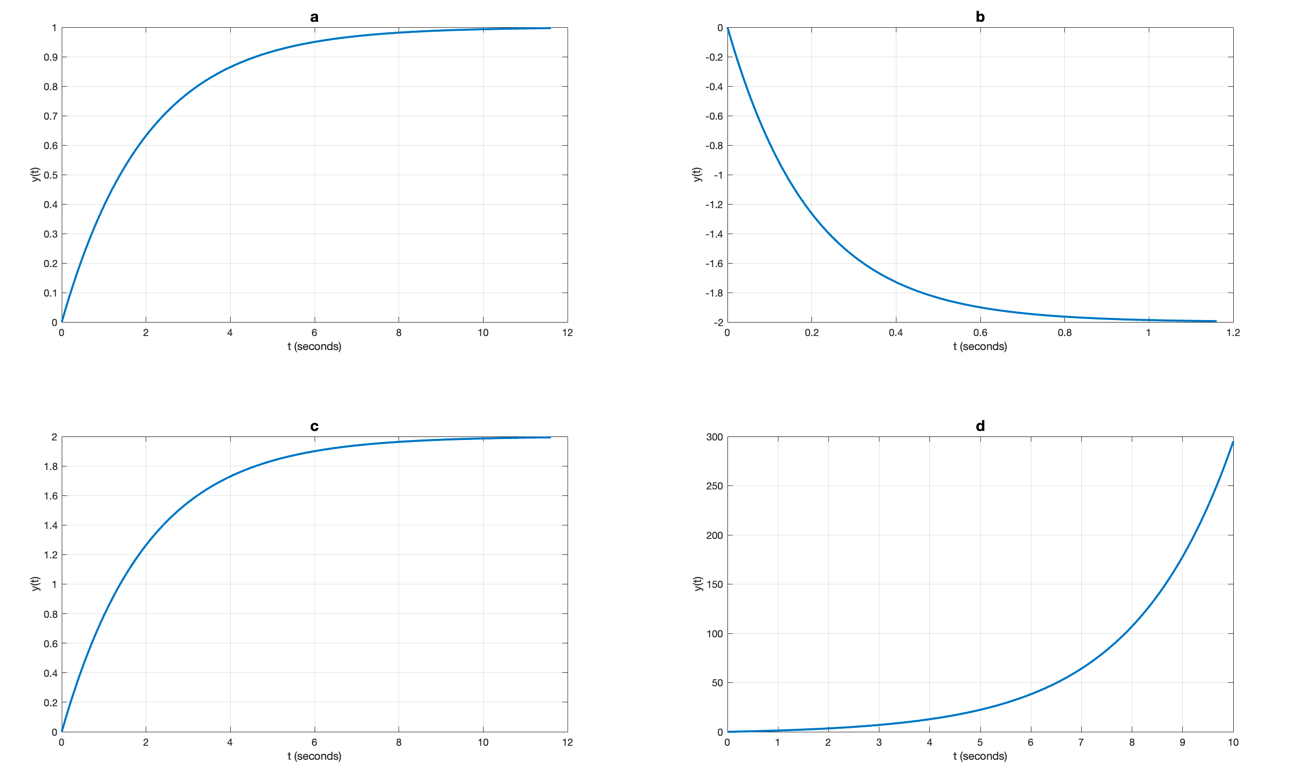

%code block to verify answers


## Second-order systems

Let us now extend the concepts of poles and zeros and transient response to second-order systems. Compared to the simplicity of a first-order system, a second-order system exhibits a wide range of responses that must be analyzed and described. The generalised second-order system with no zeros is described as

$P(s)=\frac{K}{s^2+d_1s+d_2}$.

The poles are determined by solving $s^2+d_1s+d_2=0$:

$p_{1,2}=\frac{-d_1\pm \sqrt{d_1^2-4d_2}}{2}$.

Depending on the values of $d_1$ an $d_2$ above, and assuming the poles lie in the left-half s-plane, the two poles will either be 

- strictly real and distinct (unique),

- strictly real and equivalent,

- strictly imaginary complex conjugages, or

- complex conjugates with both real and imaginary components.

### Overdamped response

A 2nd-order system is **overdamped** when the two system poles, $p_i=a_i+jb_i$, are:

- *negative-real, *$b_1=b_2=0$, $\{a_1,a_2\}<0$, and

- *distinct*: $a_1\neq a_2$,

as shown in the figure below.

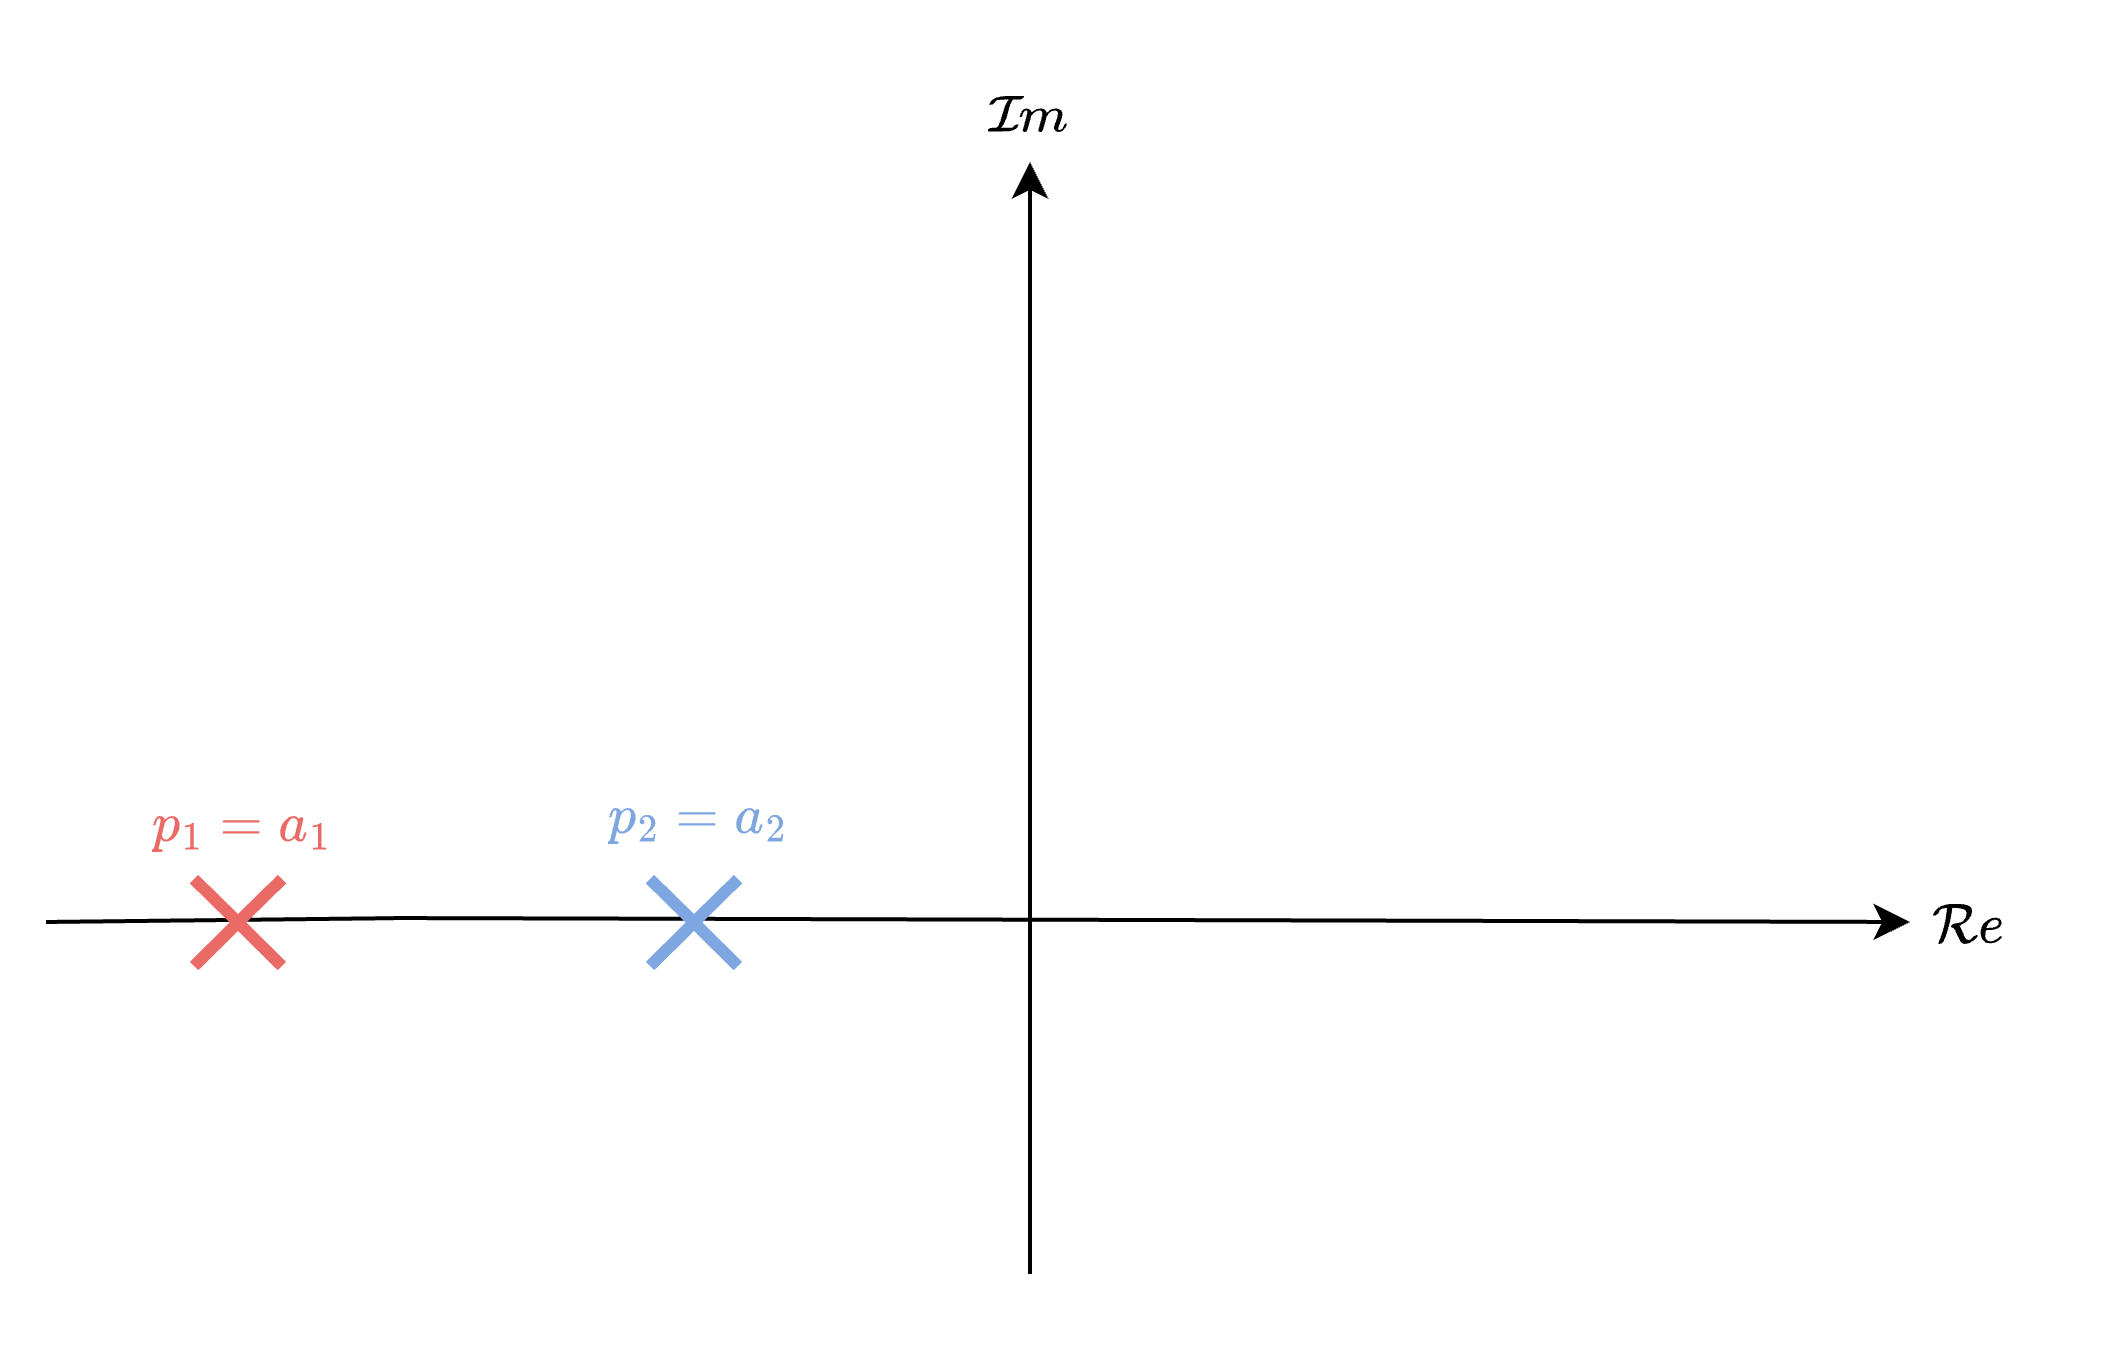

The *zero-pole-gain* representation is

$P(s)=\frac{K}{(s-p_1)(s-p_2)}=\frac{K}{s^2-(p_1+p_2)s+p_1p_2}$.

The unit step response in the Laplace domain is

$Y(s)=\frac{K}{s(s-p_1)(s-p_2)}=\frac{A}{s}+\frac{B}{s-p_1}+\frac{C}{s-p_2}$,

and using our understanding of partial fraction expansion from **Chapter 5**, the corresponding time response follows as

$\begin{array}{rl}
y(t)
&={A}+Be^{p_1t}+Ce^{p_2t},\\
&=\frac{K}{p_1p_2}+\frac{K}{p_1(p_1-p_2)}e^{p_1t}-\frac{K}{p_2(p_1-p_2)}e^{p_2t},\\
&=\frac{K}{a_1a_2}+\frac{K}{a_1(a_1-a_2)}e^{a_1t}-\frac{K}{a_2(a_1-a_2)}e^{a_2t}.\\
\end{array}$.

The code block below is used to confirm this result.

clear 
syms t s K p1 p2
P(s) = K/(s-p1)/(s-p2);
U(s) = 1/s;
Y(s) = P*U(s);
y(t) = ilaplace( Y(s) ) 

Based on the equation for $y(t)$, the steady-state value can be determined as 


$$\begin{array}{rl}
y(\infty)
&=\lim_{t\rightarrow \infty}y(t),\\
&=\frac{K}{a_1a_2},\\
&=A_{s}.\\
\end{array}$$


The unit step response has a pole at the origin that comes from the unit step input and two real poles that come from the system. The input pole at the origin generates the constant forced response; each of the two system poles on the real axis generates an exponential natural response whose exponential frequency is equal to the pole location in the $s$-plane. The unit step response and pole-zero map of $P(s)$ is generated using the code below, where $K$, $p_1=a_1$, and $p_2=a_2$ can be adjusted.

clear

K = 6;
p1 = -17;%p1=a1
p2 = -7;%p2=a2

s = tf('s');
P = K/(s-p1)/(s-p2);
[y,t] = step(P);

%y(t)
figure,clf,hold on
plot(t,y,lineWidth=2)
yline(K/p1/p2,'--k',['$A_s=\frac{K}{p_1p_2}=$',num2str(K/p1/p2,2)],Interpreter='latex',LabelVerticalAlignment='bottom')
%s-plane
figure,clf,hold on
plot(real(p1),imag(p1),'rx',MarkerSize=15)
text(real(p1),imag(p1),'  p_1=a_1',Color='r')
plot(real(p2),imag(p2),'bx',MarkerSize=15)
text(real(p2),imag(p2),'  p_2=a_2',Color='b')
yline(0),xline(0)
axis tight

The pole locations inform us of the shape of response — where all poles on the real axis (no imaginary components) implies an overdamped response. The slowest pole (the one closest to the origin) will dominate the response and will predominantly affect the settling time of the response. This is because the faster pole has a smaller time constant and its exponential term will decay quicker.

####  Question 8: What is the steady-state response of an overdamped system when a unit step input is applied?

####  Question 9: Assuming $\{d_1,d_2\}>0$, under what condition is $P(s)=\frac{K}{s^2+d_1s+d_2}$ an overdamped system?

### Critically-damped response

A 2nd-order system's output response is **critically-damped** when the two system poles, $p_i=a_i+jb_i$, are: 

- *negative-real, *$b_1=b_2=0$, $\{a_1,a_2\}<0$, and

- *equivalent*: $p_1=p_2$ (equivalently, $a_1=a_2$),

as shown in the figure below.

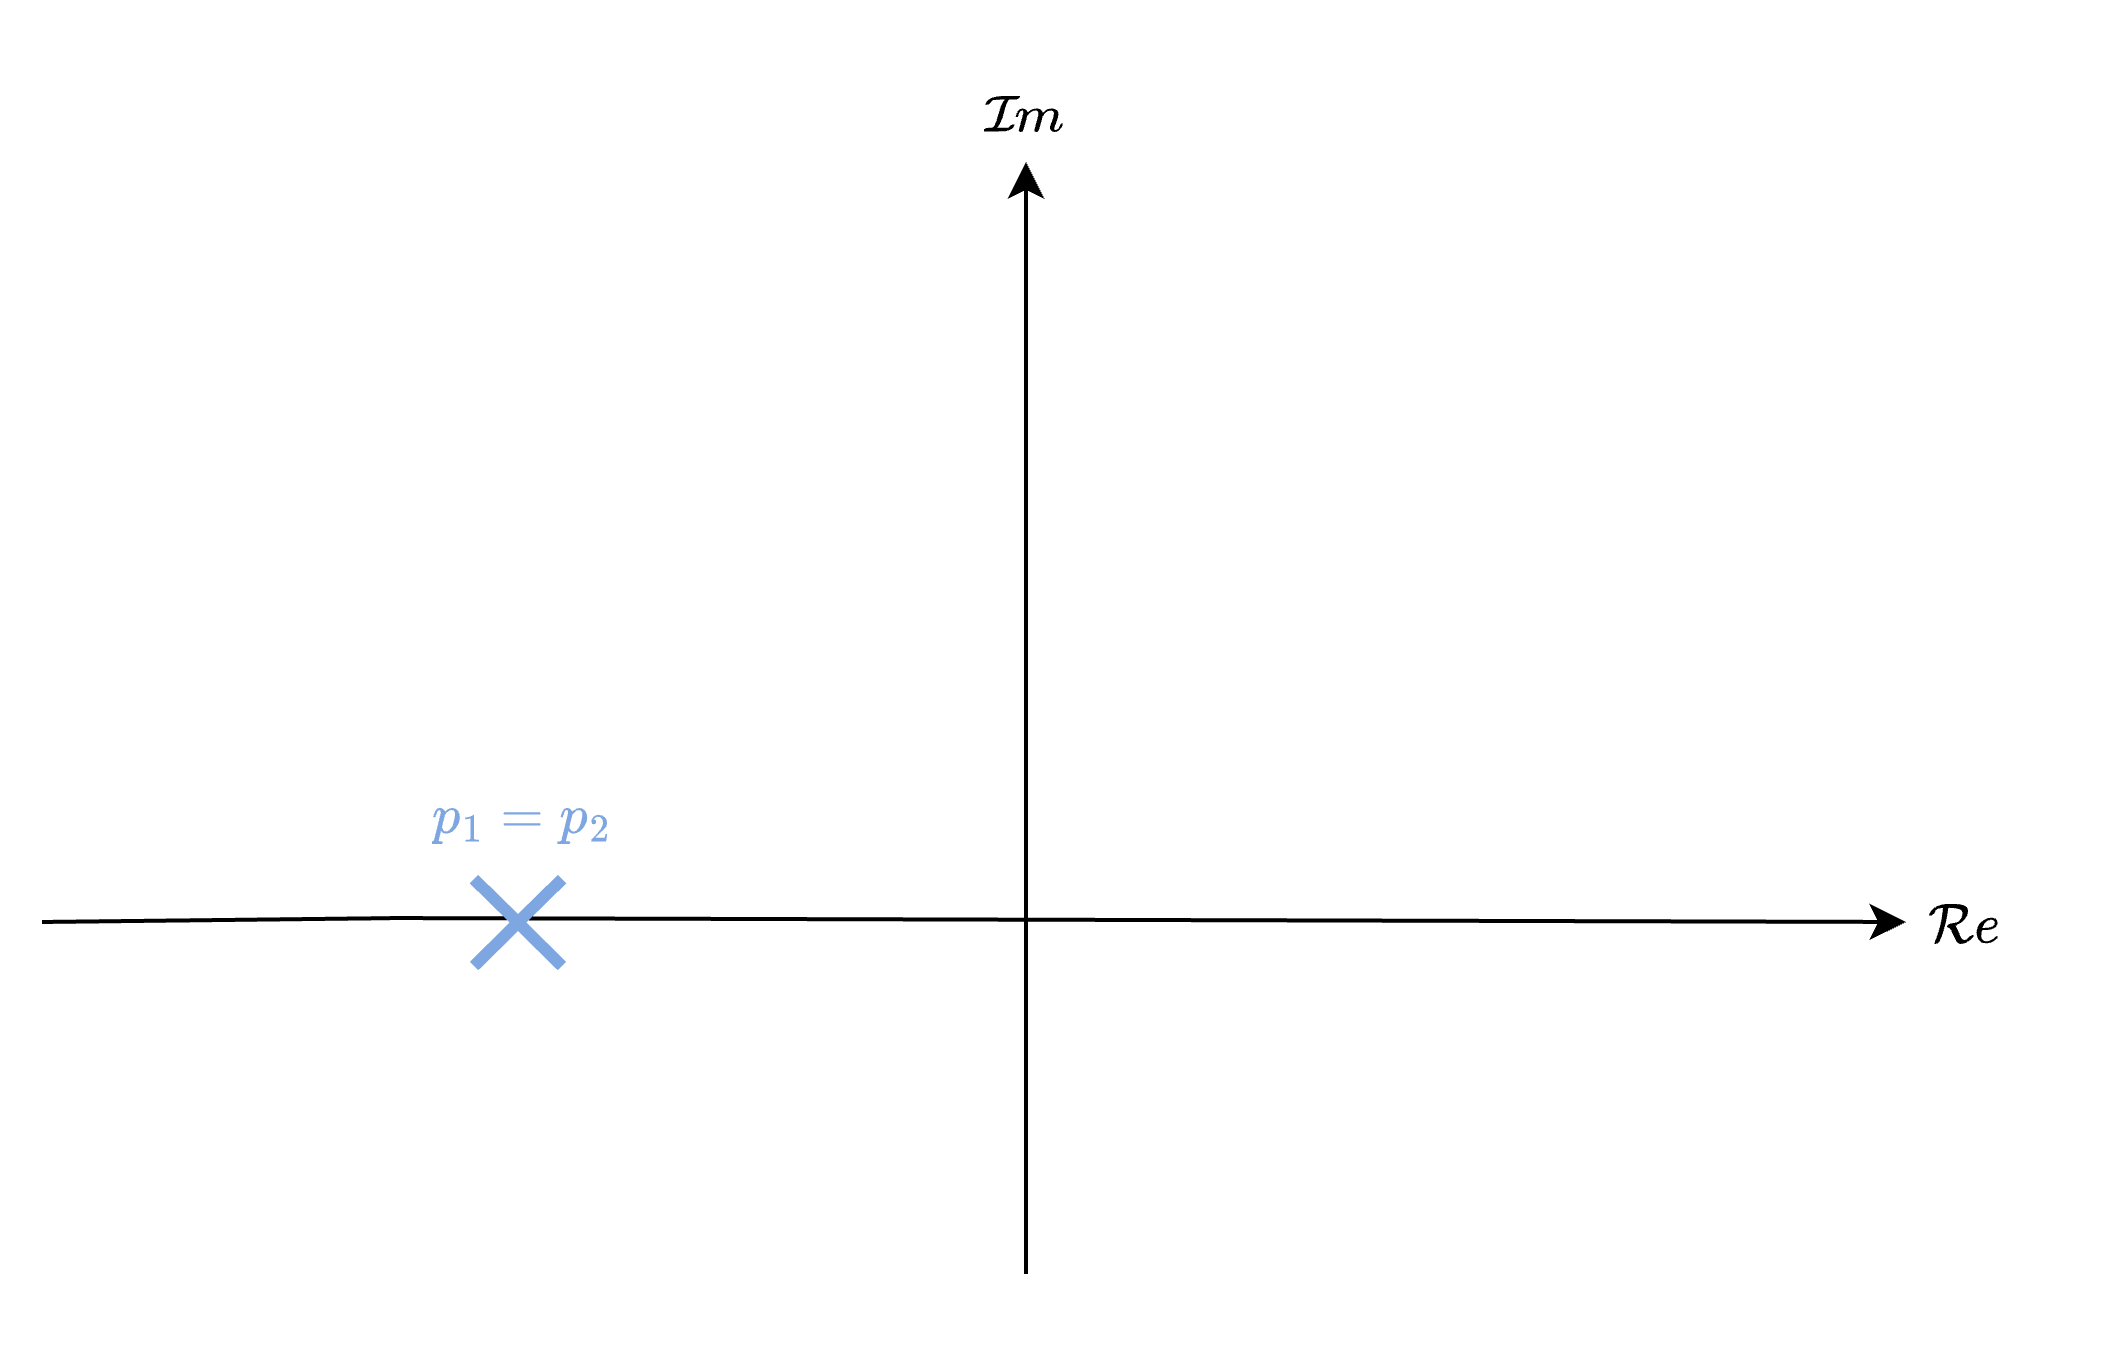

The *zero-pole-gain* representation is

$P(s)=\frac{K}{(s-p_1)^2}$.

The unit step response in the Laplace domain is

$Y(s)=\frac{K}{s(s-p_1)^2}=\frac{A}{s}+\frac{B}{(s-p_1)^2}+\frac{C}{s-p_1}$,

and the corresponding time-domain response is

$\begin{array}{rl}
y(t)
&=A+Bte^{pt}+Ce^{p_1t},\\
&=\frac{K}{p_1^2}+\frac{K}{p_1}te^{p_1t}-\frac{K}{p_1^2}e^{p_1t},\\
\end{array}$.

The code block below is used to confirm this result.

clear 
syms t s K p_1
P(s) = K/(s-p_1)^2;
U(s) = 1/s;
Y(s) = P*U(s);
y(t) = ilaplace( Y(s) ) 

Based on the equation for $y(t)$, the steady-state value can be determined as 


$$\begin{array}{rl}
y(\infty)
&=\lim_{t\rightarrow \infty}y(t),\\
&=\frac{K}{p_1^2}.
\end{array}$$


The step response is made up a step from the forced response of the input, an exponentially-decaying ramp signal, and an exponentially-decaying constant. Note the mathematical difference between the step response of a critically-damped and underdamped system. 

The unit step response and pole-zero map of $P(s)$ is generated using the code below, where $K$ and $p$ can be adjusted.

clear

K = 6;
p1 = -17;

s = tf('s');
P = K/(s-p1)^2;
[y,t] = step(P);

%y(t)
figure,clf,hold on
plot(t,y,lineWidth=2)
yline(K/p1^2,'--k',['$A_s=\frac{K}{p_1^2}=$',num2str(K/p1^2,2)],Interpreter='latex',LabelVerticalAlignment='bottom')
%s-plane
figure,clf,hold on
plot(real(p1),imag(p1),'bx',MarkerSize=15)
text(real(p1),imag(p1),'    p',Color='b')
yline(0),xline(0)
xlabel('Real axis'), ylabel('Imaginary axis')
grid on, axis tight

####  Question 10: What is the steady-state response of a critically-damped system when a unit step input is applied?

####  Question 11: Assuming $\{d_1,d_2\}>0$, under what condition(s) is $P(s)=\frac{K}{s^2+d_1s+d_2}$ a critically-damped system?

### Underdamped response

A 2nd-order system's output response is **underdamped** when the system has *complex-conjugate *poles — poles with both real and imaginary components*. *That is, two poles with equivalent negative-real components, and imaginary components that are equal in magnitude, but opposite in sign, namely

 $p_{1,2}=a\pm jb$.

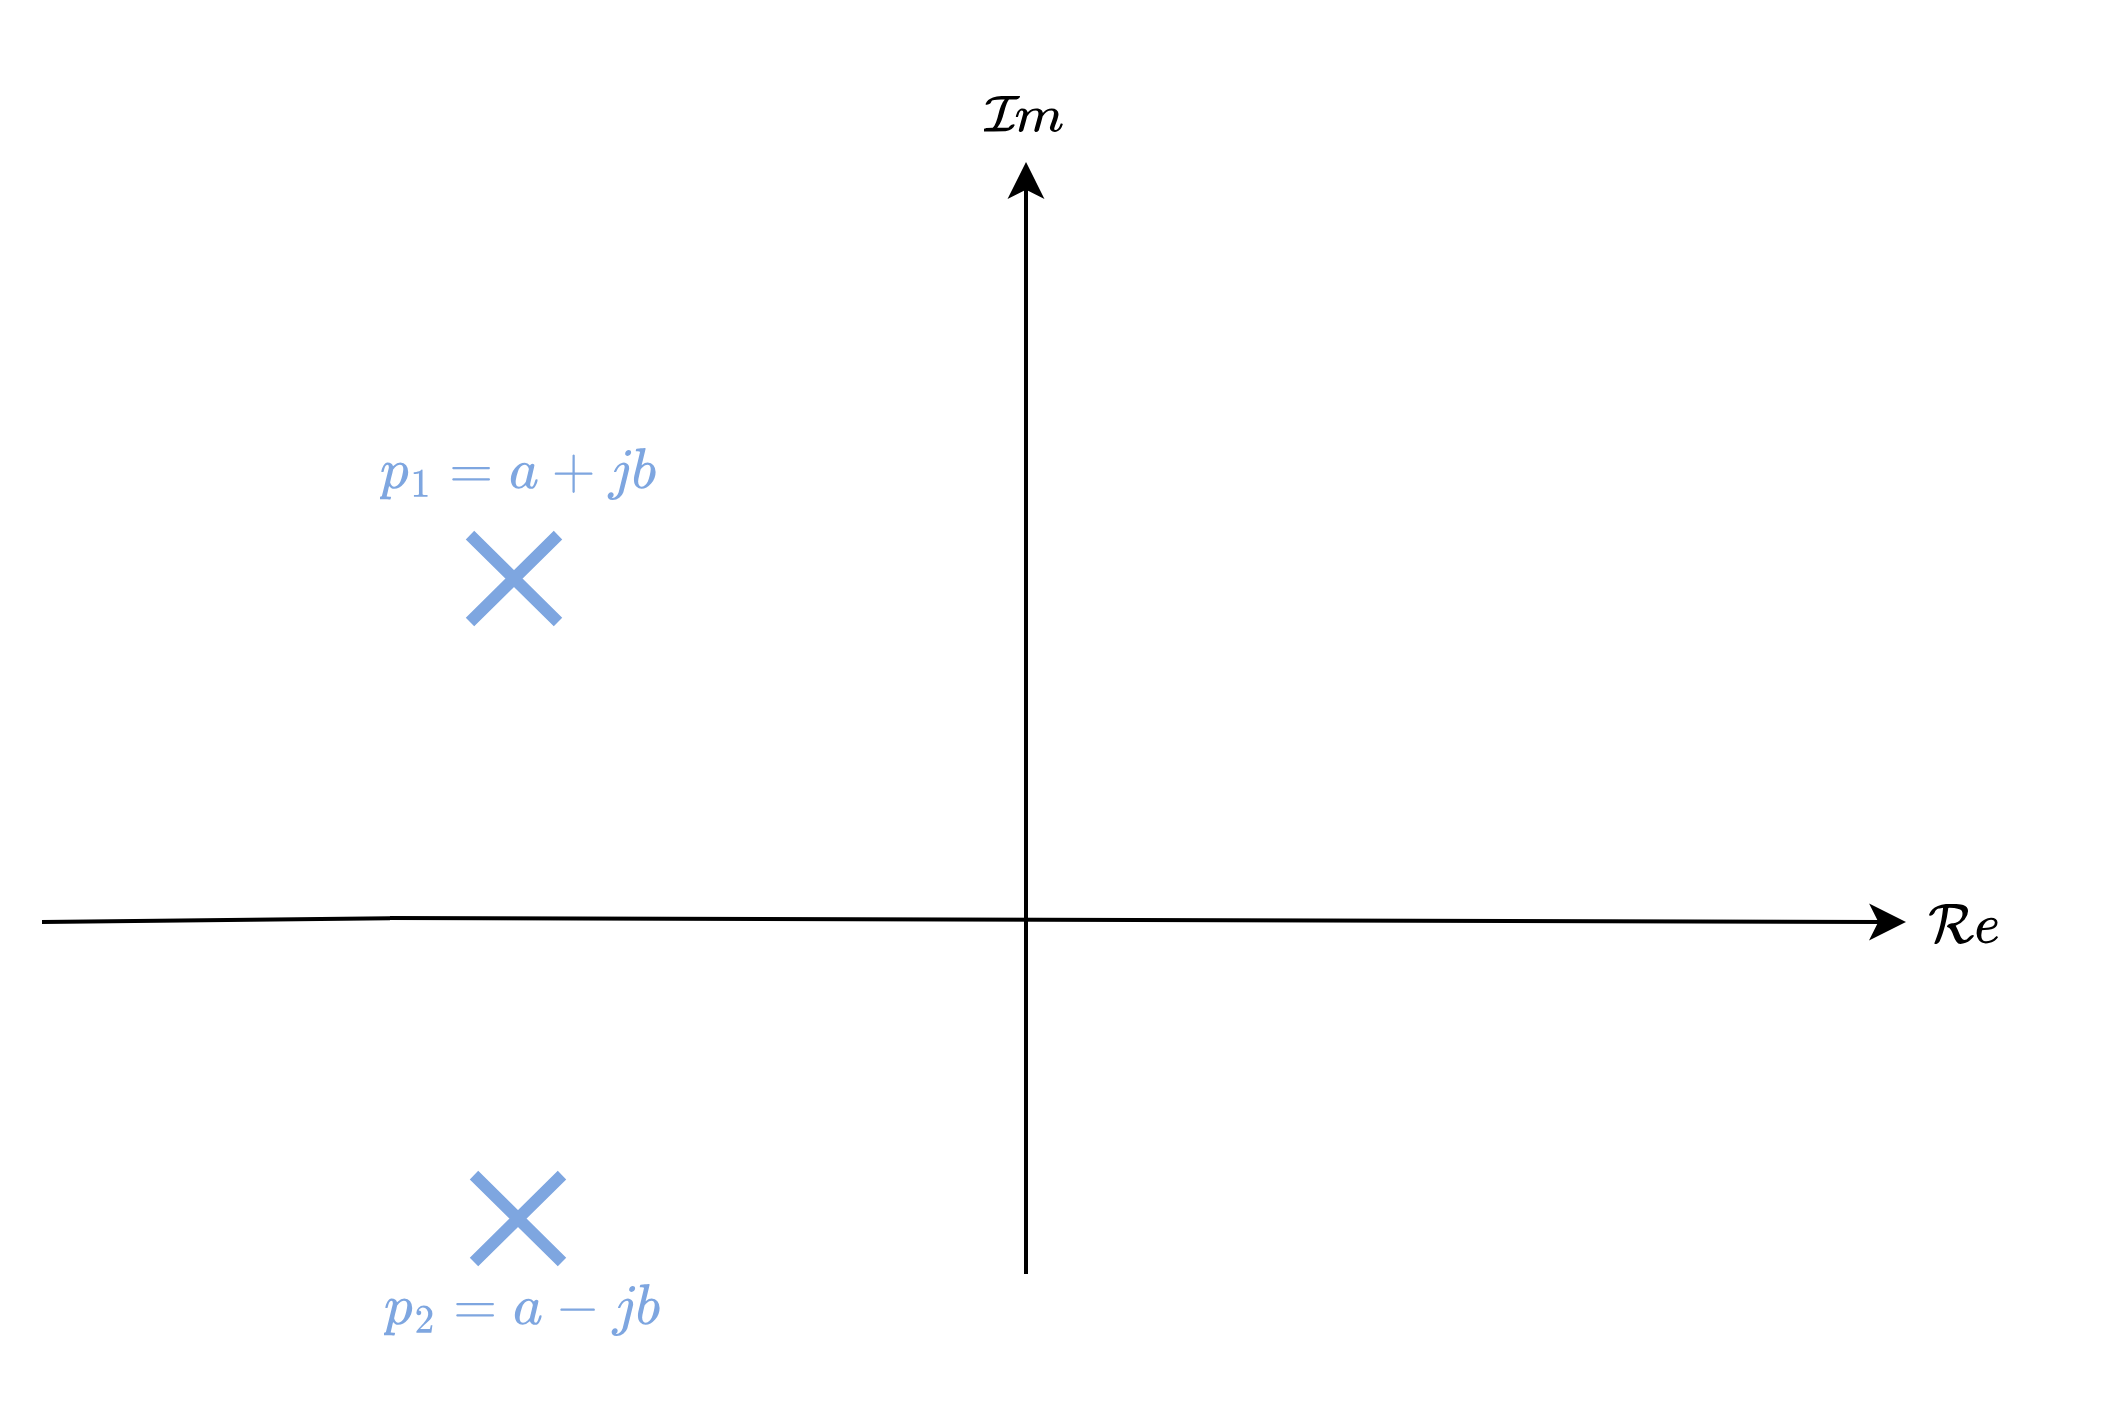

The *zero-pole-gain *representation is given as


$$\begin{array}{rl}
P(s)
&=\frac{K}{(s-a+jb)(s-a-jb)},\\
&=\frac{K}{s^2-2a s+(b^2+a^2)}.
\end{array}$$


The unit step response in the Laplace domain is given by


$$\begin{array}{rl}
Y(s)
&=\frac{K}{s(s^2-2a s+(b^2+a^2))},\\
&=\frac{A}{s}+\frac{B(s-a)+Cb}{(s-a)^2+b^2},\\
&=\frac{A}{s}+\frac{B(s-a)}{(s-a)^2+b^2}+\frac{Cb}{(s-a)^2+b^2},
\end{array}
$$


and the corresponding time-domain response is


$$\begin{array}{ll} 
y(t) 
&= A+e^{a t}\left[B\cos(a t)+C\sin(b t)\right], \\
&=A+De^{a t}\cos(b t-\phi),
\end{array}$$


where $D=\sqrt{B^2+C^2}$, and $\phi=-\tan^{-1}\frac{C}{B}$.

Note that we used the following transforms and identities:

- 
$$\sin(\omega t) = \mathcal{L}^{-1}\{ \frac{\omega}{s^2+\omega^2}\}$$


- 
$$\cos(\omega t) =\mathcal{L}^{-1}\{ \frac{s}{s^2+\omega^2}\}$$


- 
$$e^{at} f(t) = \mathcal{L}^{-1}\{ F(s-a)\}$$


Based on the structure of $Y(s)$, the steady-state value can be determined as 


$$\begin{array}{rl}
y(\infty)
&=\lim_{s\rightarrow 0}sY(s),\\
&=\lim_{s\rightarrow 0}\frac{K}{s^2-2a s+(b^2+a^2)},\\
&=\frac{K}{a^2+b^2},\\
&=A_{s}.\\
\end{array}$$


The unit step response is made up of the forced response, $A=\frac{K}{a^2+b^2}$, and a damped cosinusoid, $De^{a t}\cos(b t-\phi)$, with an exponential envelope whose time constant is equal to the reciprocal of the pole's real part, $-1/a$. The step response and pole-zero map of $P(s)$ is generated using the code below.

clear

K = 7;
a = -8;
b = 16;

s = tf('s');
p1 = a+1i*b;
p2 = a-1i*b;
P = K/(s-p1)/(s-p2);
[y,t] = step(P);

%y(t)
figure,clf,hold on
plot(t,y,lineWidth=2)
yline(K/(a^2+b^2),'--k',['$y_\infty=\frac{K}{a^2+b^2}=$',num2str(K/(a^2+b^2),3)],Interpreter='latex',LabelVerticalAlignment='bottom')
%s-plane
figure,clf,hold on
plot(real(p1),imag(p1),'bx',MarkerSize=15)
text(real(p1),imag(p1),'  p_1')
plot(real(p2),imag(p2),'bx',MarkerSize=15)
text(real(p2),imag(p2),'  p_2')
yline(0),xline(0)
grid on

####  Question 12: What is the steady-state response of an underdamped system when a unit step input is applied?

####  Question 13: Assuming $\{d_1,d_2\}>0$, under what condition(s) is $P(s)=\frac{K}{s^2+d_1s+d_2}$ an underdamped system?

The frequency of the cosine, known as the damped frequency of oscillation, is equal to the imaginary part of the poles, $b$. We also observe that the real part of the complex conjugate pole pair, $a$, contributes the exponential decay, which has the effect of dampening the oscillatory response as time progresses. We can visualise this by overlaying the step response with the exponential decay functions $\frac{K}{b^2}(1\pm e^{at})$, as shown using the code below.

clear

K = 7;
a = -3;
b = 36;

s = tf('s');
p1 = a+1i*b;
p2 = a-1i*b;
P = K/(s-p1)/(s-p2);
[y,t] = step(P);

ea = K/b^2*(1+exp(a*t));
eb = K/b^2*(1-exp(a*t));

%y(t)
figure,clf,hold on
plot(t,y,lineWidth=2)
plot(t,ea,'k--')
plot(t,eb,'k--')
yline(K/b^2,'--k',['$y_\infty=\frac{K}{b^2}=$',num2str(K/b^2,3)],Interpreter='latex',LabelVerticalAlignment='top')

line(-4/a*[1 1],[0 0.98*K/b^2],Color='red')
plot(-4/a,0.98*K/b^2,'ro',MarkerFaceColor='r')
text(-4/a,0.05*K/b^2,['T_s \approx',num2str(-4/a,2)])
xlabel('$t$ (seconds)',Interpreter='latex',FontSize=15)
ylabel('$y(t)$',Interpreter='latex',FontSize=15)

As a result, the $2\%$ settling time of an underamped 2nd-order system is approximated as

$T_s \approx\frac{-4}{a}$,

which is equivalent to the settling time of $\frac{K}{b^2}(1\pm e^{at})$. Note that the result above is a conservative approximation, as the exponential bands are only equal to the output response when the cosine function is at one of its peaks.

If we can estimate $T_s$ from a unit step response, we can then infer that the real part of our complex pole pair is $a=\frac{-4}{T_s}$. The frequency of oscillation value, $b$, can also be determined from the response by measuring the sinusoidal peak-to-peak time, $\Delta T$. The damped frequency of oscillation follows as

$b=\frac{2\pi}{\Delta T}$.

### Undamped response

A 2nd-order system's output response is **undamped** when the system has *purely imaginary conjugate poles. *That is, two poles that sit on the imaginary axis of the s-plane and are equidistant from the origin, namely

 $p_{1,2}=\pm jb$.

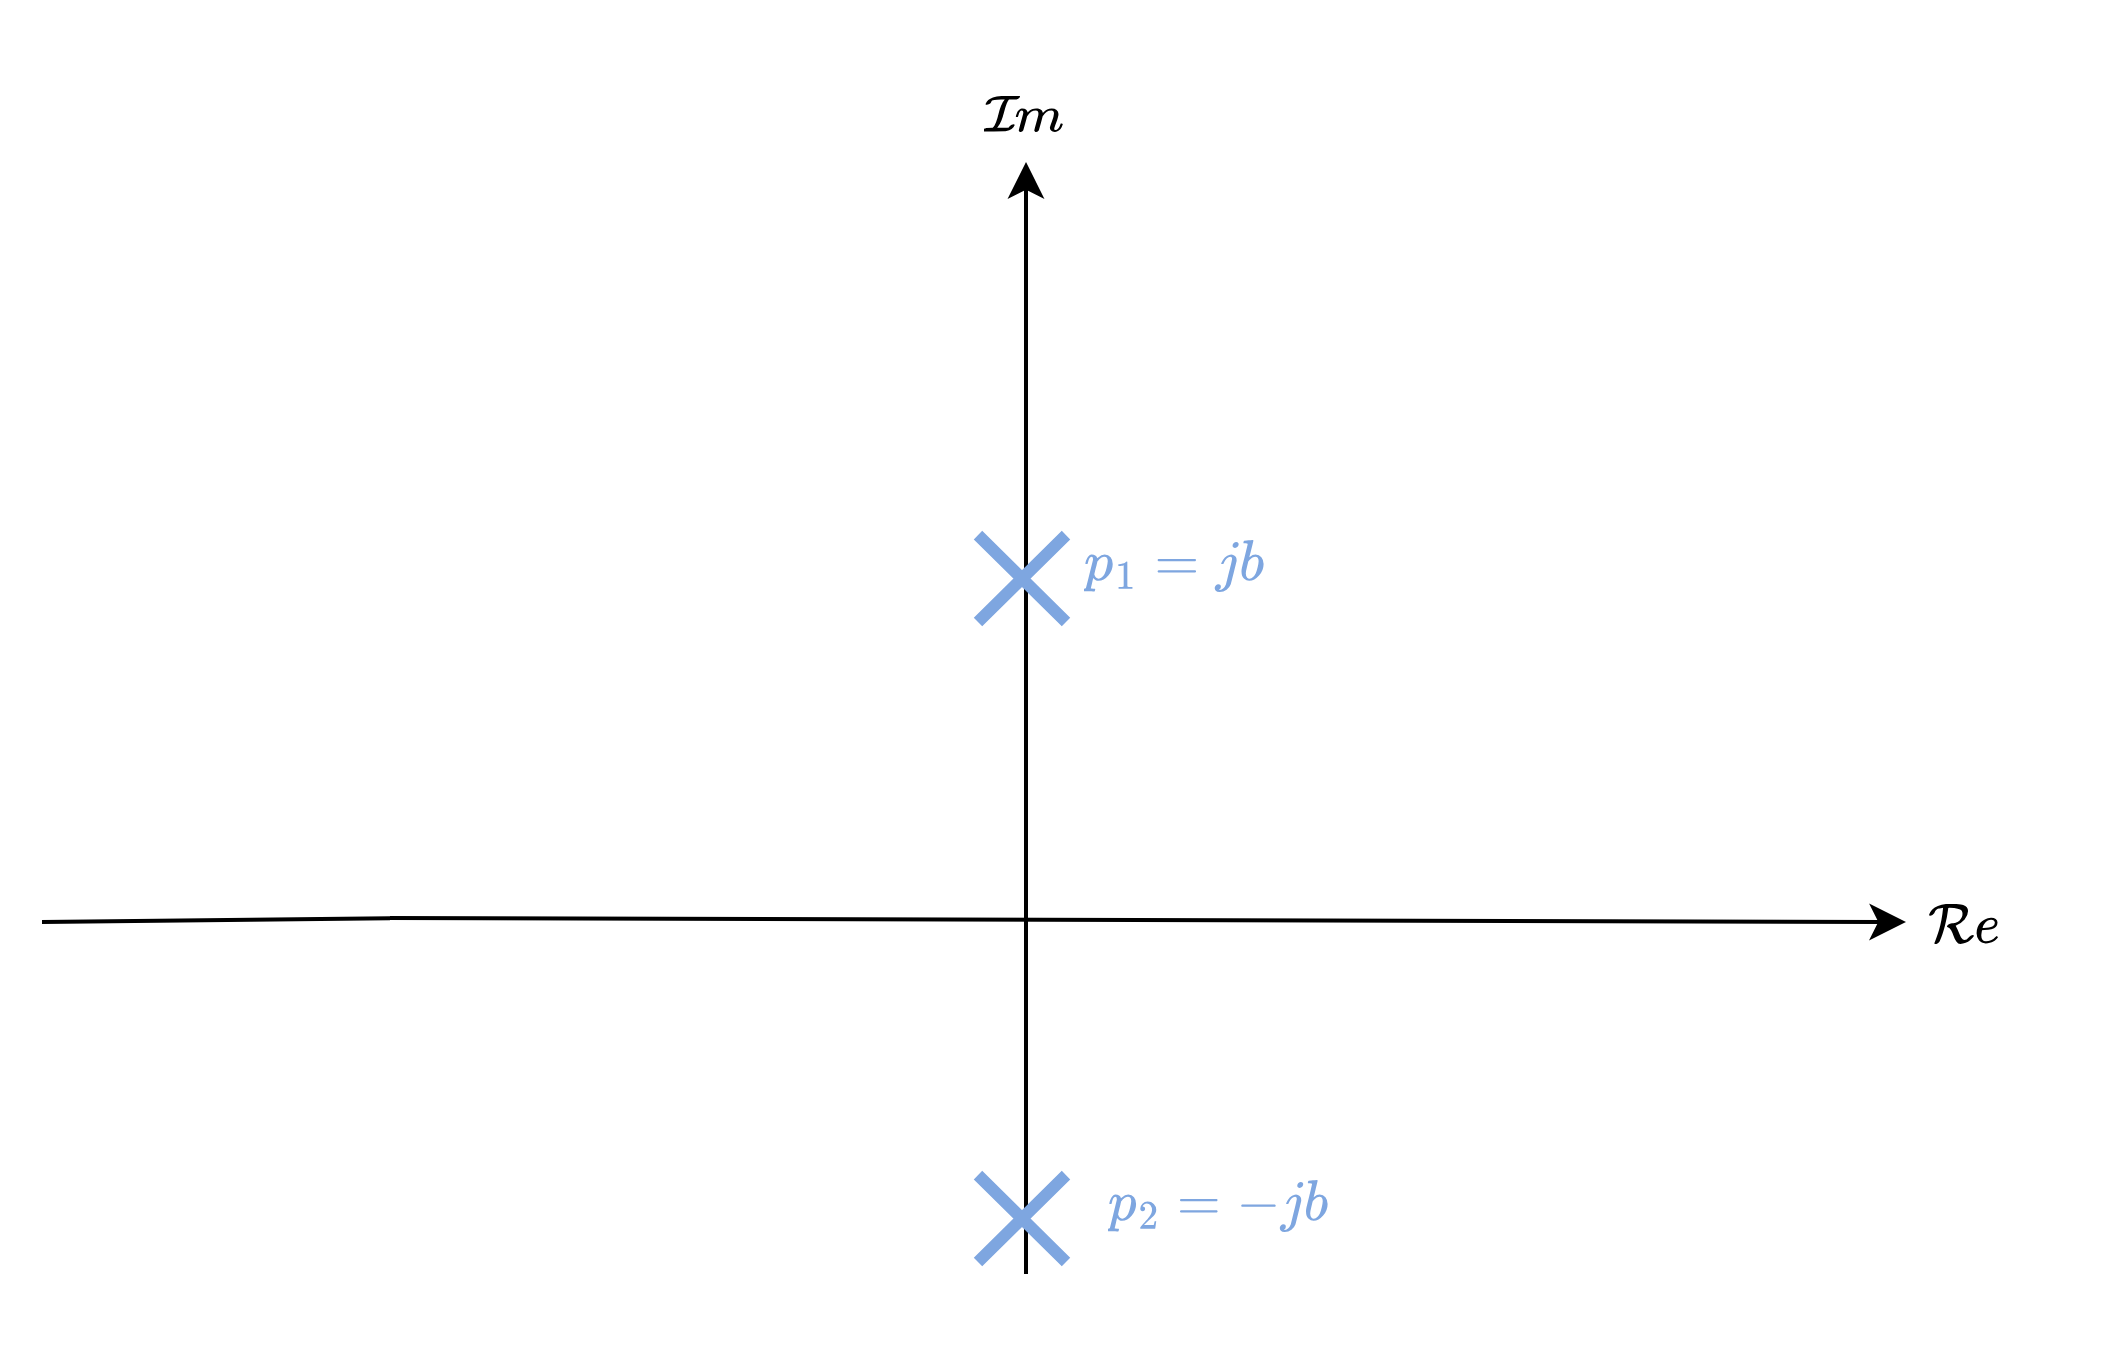

The corresponding transfer function follows as

$P(s)=\frac{K}{(s+jb)(s-jb)}=\frac{K}{s^2+b^2}$.

The unit step response in the Laplace domain is

$Y(s)=\frac{K}{s(s^2+b^2)}=\frac{A}{s}+\frac{Bs}{s^2+b^2}$,

and the corresponding time-domain response is

$\begin{array}{ll} 
y(t) 
&= A+B\cos(b t)
\end{array}$.

Note that the absence of a real part in the complex conjugate pole pair corresponds to an exponential that does not decay. Mathematically, the exponential is $e^{0t}=1$. As a result, the unit step response is made up of the forced response, $A$, and an undamped cosinusoid, $B\cos(bt)$, with a frequency of oscillation equal to the imaginary part of the poles, $b$. 

clear

K = 7;
b = 7;

s = tf('s');
P = K/(s^2+b^2);
[y,t] = step(P,10);

%y(t)
figure,clf,hold on
plot(t,y,LineWidth=2)
yline(K/b^2,'--k',['$y_\infty=\frac{K}{b^2}=$',num2str(K/b^2,3)],Interpreter='latex',LabelVerticalAlignment='bottom')
%s-plane
p1 = 1i*b;
p2 = -1i*b;
figure,clf,hold on
plot(real(p1),imag(p1),'bx',MarkerSize=15)
text(real(p1),imag(p1),'  p_1')
plot(real(p2),imag(p2),'bx',MarkerSize=15)
text(real(p2),imag(p2),'  p_2')
yline(0),xline(0)
grid on

####  Question 14: Match the second-order unit step responses below to the options provided in Amathuba.

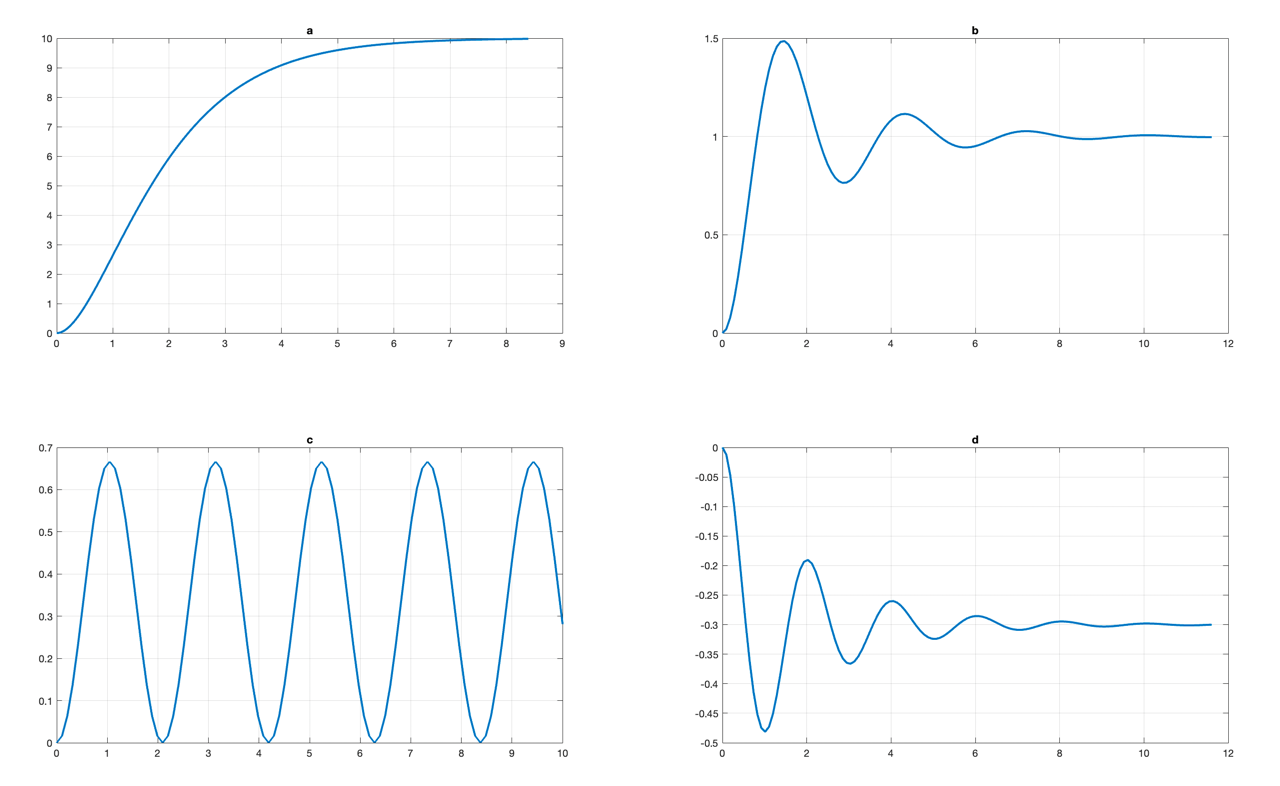

%code block to verify answers

####  Question 15: Submit your completed Virtual Lab 4 live script. **The file name must be appended with your student number, e.g. VirtualLab4_SMTJOH999.slx.**  